# Homework 1 - CEWA 473

#### The following are some typical wave conditions at various locations. Answer the questions below for each.

#### Shilshole bay: T = 4 s, d = 5 m, H = 1 m

#### Columbia River mouth: T = 12 s, d = 10 m, H = 2 m

#### S. California Bight: T = 8 s, d = 100 m, H = 3 m

#### North Pacific Ocean: T = 16 s, d = 4000 m, H = 5 m

## Question 1

#### Determine if the the waves are in shallow, intermediate, or deep water. Then, draw the corresponding wave orbital motions.

T is wave period, d is water depth, and H is wave height. We use small amplitude wave theory.

In order to determine different wave parameters, we first need to know the wave length. One method to get the wave length uses the Newton-Raphson method to iteratively obtain a numeric value from equation 3 in table 2.2 until the error is acceptable.

%The Newton Raphson Method
DecPlaces =2; % Decimal places
InitApprox = 1; % Initial appproximation
clc;
T = [4, 12, 8, 16]'; d = [5, 10, 100, 4000]'; H = [1, 2, 3, 5]'; rho = 1035; g = 9.81;
Place = ["Shilshole", "Columbia", "S. Cali", "N. Pacific"]';
places = length(Place);
syms L; Wave_Length = zeros(places, 1); iteration = Wave_Length;
for ii = 1:places
    f=(g*T(ii,1)^2/(2*pi))*tanh(2*pi*d(ii,1)/L)-L; %Enter the Function here
    [Wave_Length(ii, 1), ~] = NewtonRaphson(f, L, DecPlaces, InitApprox);
end
table(Place, Wave_Length)

ans = 4×2 table
       Place        Wave_Length
    ____________    ___________

    "Shilshole"        22.19   
    "Columbia"        113.29   
    "S. Cali"          99.92   
    "N. Pacific"      399.69   


Another method makes use of the wave table (p. 36-37).

% load the values from the wave table
Wave_Table = readmatrix('HW1_waveTable_IntroToCoastalEng3rdEd.xlsx'); % load wave table values
waveTable.dL0 = Wave_Table(:,1); waveTable.tanhkd = Wave_Table(:,2); waveTable.dL = Wave_Table(:,3); 
waveTable.kd = Wave_Table(:,4); waveTable.sinhkd = Wave_Table(:,5); waveTable.coshkd = Wave_Table(:,6); 
waveTable.n = Wave_Table(:,7);
clear Wave_Table

We then calculate the deep water length wave and relative depth.

Rel_Depth_table = zeros(places, 1); 
L0 = g.*T.^2./(2*pi); % deep water wave length
Rel_depth = d./L0; % relative deep depth d/L0
for ii = 1:places
    if Rel_depth(ii,1) < 1
        Rel_Depth_table(ii,1) = interp1(waveTable.dL0,waveTable.dL,Rel_depth(ii,1));
    else
        Rel_Depth_table(ii,1) = Rel_depth(ii,1);
    end
end
L_table = d./Rel_Depth_table;
Relative_Depth = d./Wave_Length; % d/L
k = 2*pi./Wave_Length; % wave number

table(Place, Wave_Length, Relative_Depth, L_table, Rel_Depth_table)

ans = 4×5 table
       Place        Wave_Length    Relative_Depth    L_table    Rel_Depth_table
    ____________    ___________    ______________    _______    _______________

    "Shilshole"        22.19           0.22533       22.209         0.22514    
    "Columbia"        113.29          0.088269       113.35        0.088226    
    "S. Cali"          99.92            1.0008       99.924          1.0008    
    "N. Pacific"      399.69            10.008        399.7          10.008    


The values of length in the table are in m. We can see that the wave length values obtained using wave table values and the ones obtained solving $L$ numeracally using Newton-Raphson are very similar. Next, we determine whether the waves are in shallow, intermediate, or deep water. For shallow water, $d/L< 0.05$, intermediate $0.05<d/L<0.5$, and deep $d/L>0.5$.

Depth_Condition = cell(places,1);
for ii = 1:places
    if Relative_Depth(ii,1) < 0.05
        Depth_Condition{ii,1} = "Shallow";
    elseif Relative_Depth(ii,1) > 0.5
        Depth_Condition{ii,1} = "Deep";
    else
        Depth_Condition{ii,1} = "Intermediate";
    end
end
table(Place, Depth_Condition)

ans = 4×2 table
       Place         Depth_Condition  
    ____________    __________________

    "Shilshole"     {["Intermediate"]}
    "Columbia"      {["Intermediate"]}
    "S. Cali"       {["Deep"        ]}
    "N. Pacific"    {["Deep"        ]}


The orbital diagrams are:

Shilshole Bay

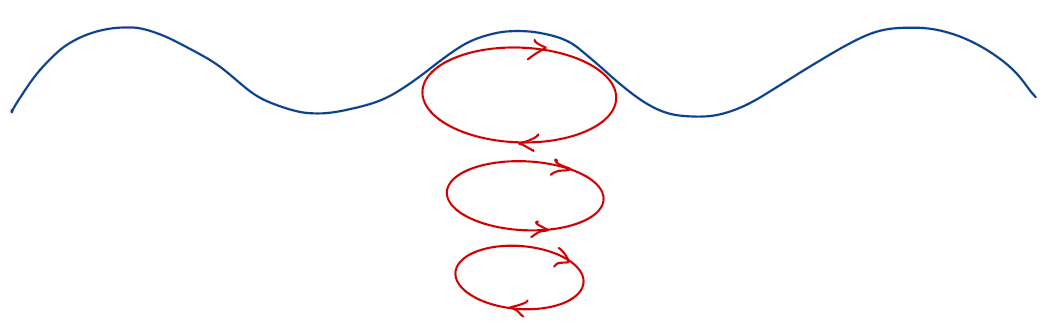

Columbia River mouth:

S. California Bight:

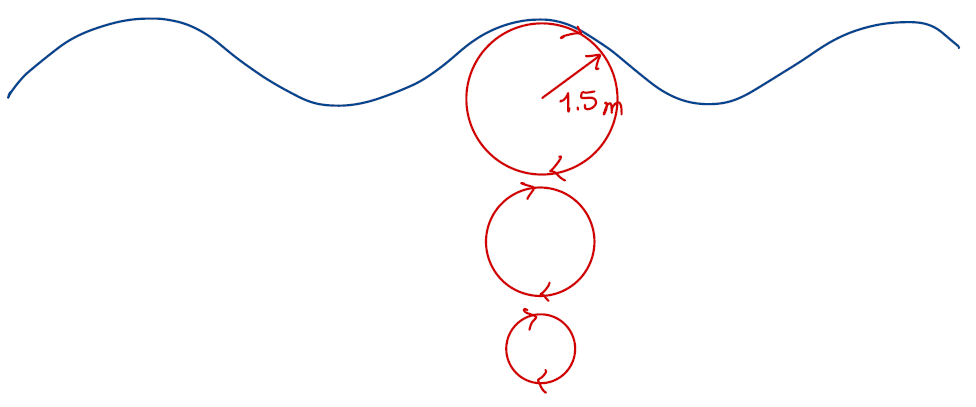

North Pacific Ocean:

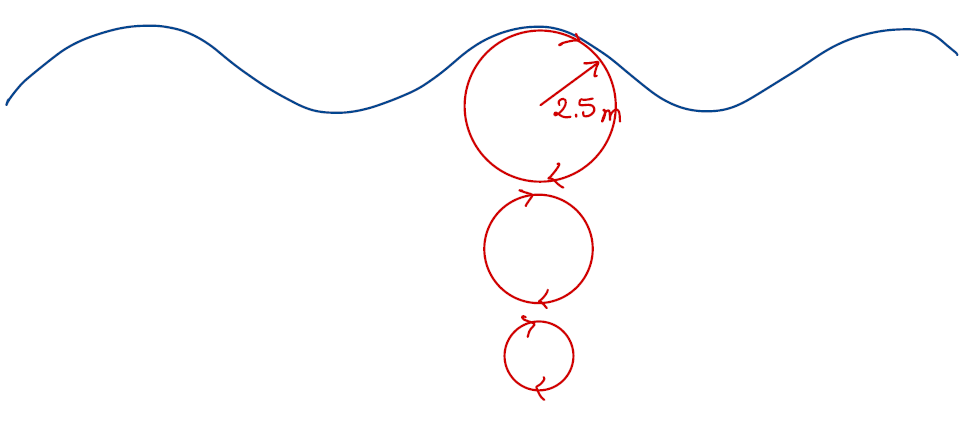

## Question 2

#### Determine the maximum particle displacements of the above waves. How do these compare with the wave heights `H`?

The actual orbital motions are:

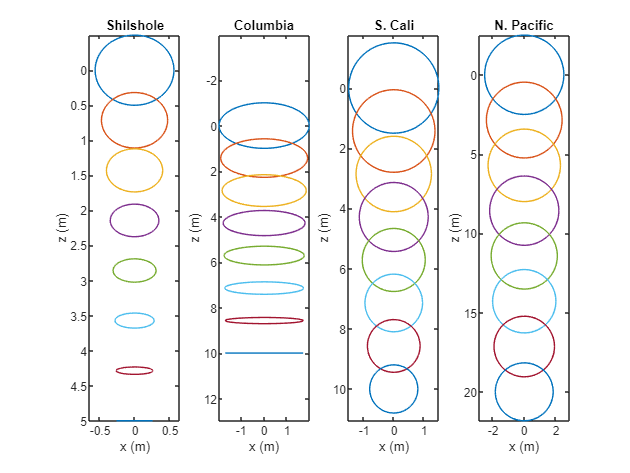

orbPt =8; % number of orbits
z = zeros(orbPt,places);
z(:,1) = linspace(0,d(1,1), orbPt)'; z(:,2) = linspace(0,d(2,1), orbPt)';
z(:,3) = linspace(0,d(3,1)/10, orbPt)'; z(:,4) = linspace(0,d(4,1)/200, orbPt)';
% clear A B A0 B0
A = zeros(size(z,1),places); B = A; % orbits axis
for ii = 1:places
    if d(ii,1)/Wave_Length(ii,1) < 0.5
        for jj = 1:orbPt
            % Horizontal orbital semi-axis
            A(jj,ii) = (H(ii)/2)*(cosh(k(ii,1)*(-z(jj,ii)+d(ii,1)))/sinh(k(ii,1)*d(ii,1)));
            % Vertical orbital semi-axis
            B(jj,ii) = (H(ii)/2)*(sinh(k(ii,1)*(-z(jj,ii)+d(ii,1)))/sinh(k(ii,1)*d(ii,1)));
            % Plot orbitals
            ang=0:0.01:2*pi; 
            xp=A(jj,ii)*cos(ang);
            yp=B(jj,ii)*sin(ang);
            subplot(1,places,ii)
            plot(xp, z(jj,ii)+yp);
            set(gca, 'YDir','reverse')
            xlabel('x (m)')
            ylabel('z (m)')
            title(sprintf('%s',Place(ii)))
            axis equal
            hold on
        end
    else
        % For deep water
        for jj = 1:orbPt
            % Horizontal orbital semi-axis
            A(jj,ii) = (H(ii)/2)*exp(-z(jj,ii)*k(ii,1));
            % Vertical orbital semi-axis
            B(jj,ii) = A(jj,ii);
            % Plot orbitals
            ang=0:0.01:2*pi;
            xp=A(jj,ii)*cos(ang);
            yp=B(jj,ii)*sin(ang);
            subplot(1,places,ii)
            plot(xp, z(jj,ii)+yp);
            set(gca, 'YDir','reverse')
            xlabel('x (m)')
            ylabel('z (m)')
            title(sprintf('%s',Place(ii)))
            axis equal
            hold on
        end
    end
    clear ang xp yp L0_orb
    hold off
end

The maximum particle displacement will occur at the surface since $z = 0$.

Max_displacement = zeros(places, 1);
for ii = 1:places
    Max_displacement(ii,1) = 2 * max(A(1,ii), B(1,ii));
end
table(Place, Max_displacement)

ans = 4×2 table
       Place        Max_displacement
    ____________    ________________

    "Shilshole"          1.1252     
    "Columbia"           3.9685     
    "S. Cali"                 3     
    "N. Pacific"              5     


The values in the table are in m. We can observe that for intermediate depths, the maximum particle displacement is greater than $H$ because the orbit is ellipsoidal and the maximum displacement is horizontal, but for deep waters the maximum particle displacement is equal to $H$ due to the circular orbit of the particles.

##  Question 3

#### Determine the maximum pressure variation at the seabed caused by each of these waves. How do these compare with atmospheric pressure?

We now need to determine the pressure variation. For this, we first calculate the pressure response factor, $K_p$ at the bottom. The pressure at the seabed is $K_pH$ in m of water or $\rho g K_p H / 1000$ in kPa.

theta = [0; pi/2; pi; 3*pi/2];
Kp_B = 1./cosh(k.*d); % pressure response factor at seabed
for ii = 1:length(theta)
    Pressure_variation_Seabed(:,ii) = rho.*g.*((H/2).*cos(theta(ii,1))./T).*Kp_B./1000; % kPa
end


table(Place, Kp_B, Pressure_variation_Seabed)

ans = 4×3 table
       Place           Kp_B                      Pressure_variation_Seabed               
    ____________    __________    _______________________________________________________

    "Shilshole"        0.45846       0.58187     3.5629e-17       -0.58187    -1.0689e-16
    "Columbia"         0.86372       0.73081     4.4749e-17       -0.73081    -1.3425e-16
    "S. Cali"        0.0037161     0.0070746     4.3319e-19     -0.0070746    -1.2996e-18
    "N. Pacific"    9.8251e-28    1.5587e-27     9.5444e-44    -1.5587e-27    -2.8633e-43


The pressure variation values in the table are in kPa. Kp_B is the pressure response factor. We can observe that all the values obtained are much smaller that the atmospheric pressure (101 kPa) nad that the pressure variation is the highest at the crest ($\theta=2\pi n$, column 3 in table), is zero at the still water level ($\theta = n\pi /2$, column 4 and 6 in table), and negative at the trough ($\theta=n\pi$, column 5 in table).  Also, we can notice that  the pressure varation is not felt in very deep waters.

## Question 4

#### What is the energy flux, per unit crest length, carried by each of these waves? How does this compare with solar insolation per unit surface area?

Equation 2.10 expresses the wave energy per unit surface area, in joules/m$^2$.  Equation 2.11 gives wave power, $P$, arriving at any location. Its units are watt/m of wave crest.

Group_Vel_Param = 0.5.*(1 + (2.*k.*d)./(sinh(2.*k.*d)));
Wave_velocity = Wave_Length./T; % m/s
Group_velocity = Group_Vel_Param.*Wave_velocity; % m/s
Energy_Density = (1/8).*rho.*g.*H; % joules/m2
Energy_Flux = Energy_Density.*Group_velocity; % watts/m of wave crest

table(Place, Group_Vel_Param, Wave_velocity, Group_velocity, Energy_Density, Energy_Flux)

ans = 4×6 table
       Place        Group_Vel_Param    Wave_velocity    Group_velocity    Energy_Density    Energy_Flux
    ____________    _______________    _____________    ______________    ______________    ___________

    "Shilshole"         0.66742           5.5475            3.7025            1269.2          4699.1   
    "Columbia"          0.91049           9.4408            8.5958            2538.3           21819   
    "S. Cali"           0.50004            12.49            6.2455            3807.5           23780   
    "N. Pacific"            0.5           24.981             12.49            6345.8           79262   


The wave velocity values in the table are in m/s, energy density in Joules/m$^2$, energy flux in watts/m of wave crest. The solar insolation (or average global energy flux from the sun to the oceans) is 1000 watts/m$^2$. We can observe that  for deep depths, the energy flux carried by each wave grows larger that the annual insolation energy; whereas these two values get closer  the shallower the flow is.

## Question 5

#### If appropriate (if theory is valid) calculate the Stokes drift of each of these waves. Can a human swim faster than this?

For a pure wave motion in fluid dynamics, the **Stokes drift velocity** is the average velocity when following a specific fluid parcel as it travels with the fluid flow. For instance, a particle floating at the free surface of water waves, experiences a net Stokes drift velocity in the direction of wave propagation.

Wave_Steepness = H./Wave_Length;
Relative_Wave_Height = H./d;
Ursel_Number = (Wave_Length.^2 .* H)./d.^3;

table(Place, Wave_Steepness, Relative_Wave_Height, Ursel_Number)

ans = 4×4 table
       Place        Wave_Steepness    Relative_Wave_Height    Ursel_Number
    ____________    ______________    ____________________    ____________

    "Shilshole"        0.045065                 0.2                3.9392 
    "Columbia"         0.017654                 0.2                25.669 
    "S. Cali"          0.030024                0.03              0.029952 
    "N. Pacific"        0.01251             0.00125            1.2481e-05 


Stokes theory is valid when the Ursel number, $U_r < 79$.

Stokes_Drift = zeros(orbPt,places);
for ii = 1:places
    for jj = 1: orbPt
        if Ursel_Number(ii,1) < 79
            Stokes_Drift(jj,ii) = (pi*H(ii,1)/Wave_Length(ii,1)).^2.*(cosh(2.*k(ii,1)*(-z(jj,ii)+d(ii,1)))./sinh(k(ii,1).*d(ii,1)).^2);
        end
    end
end
Stokes_Drift_Surf = Stokes_Drift(1,:)'; % Stokes Drift at the surface

table(Place, Ursel_Number, Stokes_Drift_Surf)

ans = 4×3 table
       Place        Ursel_Number    Stokes_Drift_Surf
    ____________    ____________    _________________

    "Shilshole"          3.9392         0.045422     
    "Columbia"           25.669         0.015187     
    "S. Cali"          0.029952         0.017794     
    "N. Pacific"     1.2481e-05         0.003089     


The Stokes drift values in the table are in m/s. Assuming that an average human can reach velocities of 0.8 m/s, we can conclude that an average person can swim faster thatn the Stokes drift of all the waves above.

## Question 6

#### Find a valid nonlinear theory for each wave. Are any of these waves close to breaking?

To find a valid non-linear theory for each wave, we use figure 2.7 and the data in the table below.

table(Place, Depth_Condition, Wave_Steepness, Relative_Depth)

ans = 4×4 table
       Place         Depth_Condition      Wave_Steepness    Relative_Depth
    ____________    __________________    ______________    ______________

    "Shilshole"     {["Intermediate"]}       0.045065           0.22533   
    "Columbia"      {["Intermediate"]}       0.017654          0.088269   
    "S. Cali"       {["Deep"        ]}       0.030024            1.0008   
    "N. Pacific"    {["Deep"        ]}        0.01251            10.008   


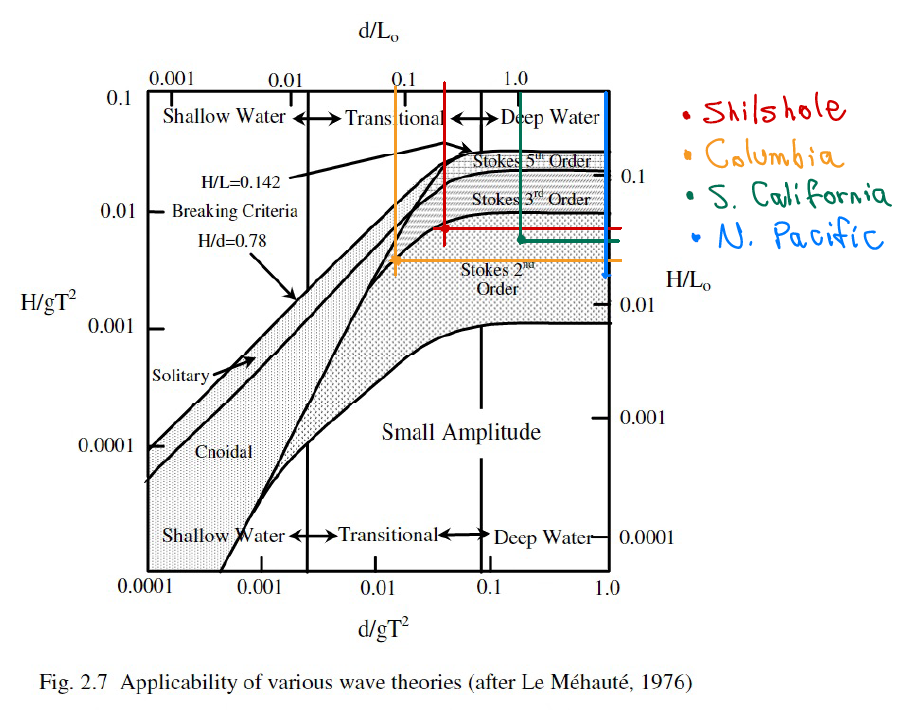

From the figure, we can see that Shilshole Bay, Columbia River Mouth, S. California Bight and the North Pacific Ocean fall within the Stokes 2nd order range. Columbia can also be modeled using Cnoidal Theory since it falls close the the Cnoidal area in figure 2.7.

Wave breaking criterion (equation 15, table 2.2).

Wave_Breaking_Criterion = cell(places, 1); WBC = Wave_Breaking_Criterion;
Breaking_Limit = zeros(places, 1);
for ii = 1:places
    % Using expression
    Breaking_Limit(ii,1) = 0.142*tanh(k(ii)*d(ii));
    if Wave_Steepness(ii,1) < Breaking_Limit(ii,1)
        Wave_Breaking_Criterion{ii,1} = "Not Breaking";
    else
        Wave_Breaking_Criterion{ii,1} = "Breaking";
    end
end
table(Place, Wave_Steepness, Relative_Wave_Height, Breaking_Limit, Wave_Breaking_Criterion)

ans = 4×5 table
       Place        Wave_Steepness    Relative_Wave_Height    Breaking_Limit    Wave_Breaking_Criterion
    ____________    ______________    ____________________    ______________    _______________________

    "Shilshole"        0.045065                 0.2                0.1262         {["Not Breaking"]}   
    "Columbia"         0.017654                 0.2              0.071563         {["Not Breaking"]}   
    "S. Cali"          0.030024                0.03                 0.142         {["Not Breaking"]}   
    "N. Pacific"        0.01251             0.00125                 0.142         {["Not Breaking"]}   


where `Breaking_Limit `$=0.142\tanh(kd)$. We can observe that none of the waves are breaking.